## Lab 3 Sample Solution

### Task 1

Linearize the magnetic ball suspension system using the state space approach about the equilibrium point 0.01 m (where nominal current is about 7 A) and derive A∗ and B∗ . Use M = 0.05 kg, K = 0.0001, L = 0.01 H, R = 1 Ω, g = 9.81 m s−2 . In the output we will only be measuring the height of the ball h(t).

% Hints:
% Define A, B, C, D following eqution 25, 26 using the provided constants

x_01 = 0.01;
M = 0.05;
K = 0.0001;
L = 0.01;
R = 1;
g = 9.81;

 A = [0 1 0;
     K*g/x_01 0 -2*K*sqrt(g/(M*x_01));
     0 0 -R/L];

B = [0;
    0;
    1/L];

C = [1 0 0];
D = 0;

### Task 2

Use MATLAB to write a script to model the system using your linearized matrices. Implement in your code to find the poles of the system.

% Hints:
% sys = ss(A,B,C,D) creates a continuous-time state-space model object.
% pole(sys) returns poles of the system.
% disp(poles) to show the values.

sys = ss(A, B, C, D);
poles = pole(sys);
disp(poles)

    0.3132
   -0.3132
 -100.0000



### Task 3

Add a constant input v(t) = 0 with initial condition x0 = [0.01 0 0]T into your code and run a linear simulation in MATLAB to view the open loop response to the system.

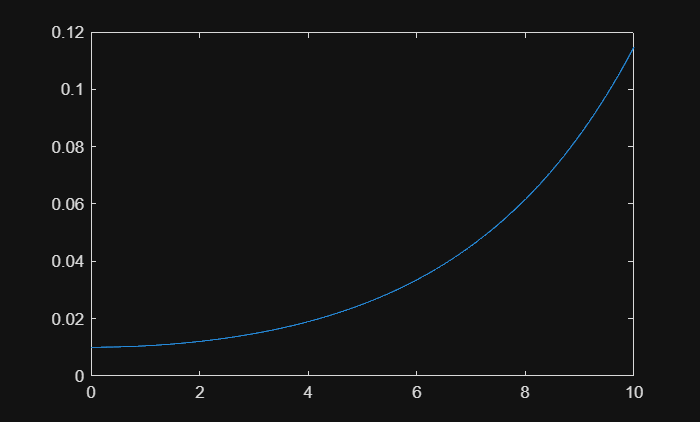

% Hints:
% define x_0, t, and input
t = 0:0.01:10;  
input = zeros(size(t));
x_0 = [0.01; 0; 0];

% Use h = lsim(sys, input, t, x_0) for linear simulation
h = lsim(sys, input, t, x_0);
plot(t, h);


% plot(t,h)

### Task 4

Repeat Task 3 in Simulink. Attach the screenshot of the model and the scope output below.

Hints:

- Pass a constant zero input to a State-Space block followed by a Scope block.

- Set the existing variable values of A, B, C, D and x_0 in the State-Space parameters.

### Task 5

- Use MATLAB’s own built-in function to convert the state space representation to transfer function representation

% Hints:
% use [num, den] = ss2tf(A,B,C,D) to convert state-space representation into a transfer
% function.
% display the transfer function

[num, den] = ss2tf(A, B, C, D);
transfer_fcn1 = tf(num, den)


transfer_fcn1 =
 
              -2.801
  -------------------------------
  s^3 + 100 s^2 - 0.0981 s - 9.81
 
Continuous-time transfer function.


- Use Equation 10 to compute transfer function from state space model symbolically in MATLAB. You will need to initialize the variable s with the function tf()

% use tf("s") creates special variable s that can be used to create a continuous-time transfer function model
% equation 10: transfer_fcn = C*inv(s*I - A)*B+D; where I = eye(size(A,1))
% the transfer function should match the output from the code block above.
s = tf("s");
I = eye(size(A,1));
transfer_fcn2 = C*inv(s*I - A)*B+D


transfer_fcn2 =
 
              -2.801
  -------------------------------
  s^3 + 100 s^2 - 0.0981 s - 9.81
 
Continuous-time transfer function.


The transfer_fcn1 and transfer_fcn2 should match.

### Post Lab

1. Find the poles and zeroes of the system and generate a pole-zero map. Draw or printout that map in your notebook.

2. Comment on the output of Task 2 and the positions of the poles of the system. What do they tell you about system stability?

3. Do you think the system is stable? If yes, why?

4. Is the system observable with the output provided?

5. Is the system controllable with the inputs provided?

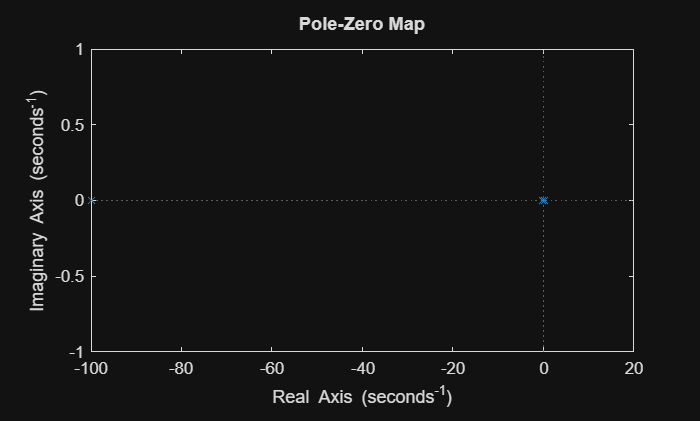

% Hints:
% use pzmap(sys) for poles and zeros
% use rank(obsv(sys)) for rank of observability matrix (should be non-zero)
% use rank(ctrb(sys)) for rank of controllability matrix (should be non-zero)

pzmap(sys)

[p, z] = pzmap(sys)

p =     0.3132
   -0.3132
 -100.0000



z =

  0×1 empty double column vector




obsv(A, C);
obsv_rank = rank(obsv(sys));
disp(obsv_rank);

     3




ctrb(A, B);
ctrb_rank = rank(ctrb(sys));
disp(ctrb_rank);

     3

